Fi = 1e3

Fi = 1000

Fs = 5e4

Fs = 50000

Tstop = 0.2

Tstop = 0.2000

mdl = "class_d_mfb"

mdl = "class_d_mfb"

simin = Simulink.SimulationInput(mdl)

simin =   SimulationInput with properties:

               ModelName: "class_d_mfb"
            InitialState: [0×0 Simulink.op.ModelOperatingPoint]
           ExternalInput: []
         ModelParameters: [0×0 Simulink.Simulation.ModelParameter]
         BlockParameters: [0×0 Simulink.Simulation.BlockParameter]
               Variables: [0×0 Simulink.Simulation.Variable]
               PreSimFcn: []
              PostSimFcn: []
              UserString: ''
    VariantConfiguration: ''



simin = setModelParameter(simin, ...
    "StopTime", string(Tstop))

simin =   SimulationInput with properties:

               ModelName: "class_d_mfb"
            InitialState: [0×0 Simulink.op.ModelOperatingPoint]
           ExternalInput: []
         ModelParameters: [1×1 Simulink.Simulation.ModelParameter]
         BlockParameters: [0×0 Simulink.Simulation.BlockParameter]
               Variables: [0×0 Simulink.Simulation.Variable]
               PreSimFcn: []
              PostSimFcn: []
              UserString: ''
    VariantConfiguration: ''


input = strcat(mdl, "/Sine Wave")

input = "class_d_mfb/Sine Wave"

simin = setBlockParameter(simin, input, "Frequency", string(2*pi*Fi))

simin =   SimulationInput with properties:

               ModelName: "class_d_mfb"
            InitialState: [0×0 Simulink.op.ModelOperatingPoint]
           ExternalInput: []
         ModelParameters: [1×1 Simulink.Simulation.ModelParameter]
         BlockParameters: [1×1 Simulink.Simulation.BlockParameter]
               Variables: [0×0 Simulink.Simulation.Variable]
               PreSimFcn: []
              PostSimFcn: []
              UserString: ''
    VariantConfiguration: ''



output = strcat(mdl, "/Sampled Output")

output = "class_d_mfb/Sampled Output"

simin = setBlockParameter(simin, output, "SampleTime", string(1/Fs))

simin =   SimulationInput with properties:

               ModelName: "class_d_mfb"
            InitialState: [0×0 Simulink.op.ModelOperatingPoint]
           ExternalInput: []
         ModelParameters: [1×1 Simulink.Simulation.ModelParameter]
         BlockParameters: [1×2 Simulink.Simulation.BlockParameter]
               Variables: [0×0 Simulink.Simulation.Variable]
               PreSimFcn: []
              PostSimFcn: []
              UserString: ''
    VariantConfiguration: ''



out = sim(simin)

### Building the rapid accelerator target for model: class_d_mfb
### Successfully built the rapid accelerator target for model: class_d_mfb


out =   Simulink.SimulationOutput:

                   tout: [21909161x1 double] 
             continuous: [1x1 struct] 
               discrete: [10001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


timeseries = get(out, "continuous")

timeseries = struct with fields:
         time: [21909161×1 double]
      signals: [1×1 struct]
    blockName: 'class_d_mfb/Continuous Output'


sampled = get(out, "discrete")

sampled =          0
    3.2366
    7.5151
   11.3096
   14.9769
   18.4233
   21.5437
   24.3602
   26.7597
   28.7498


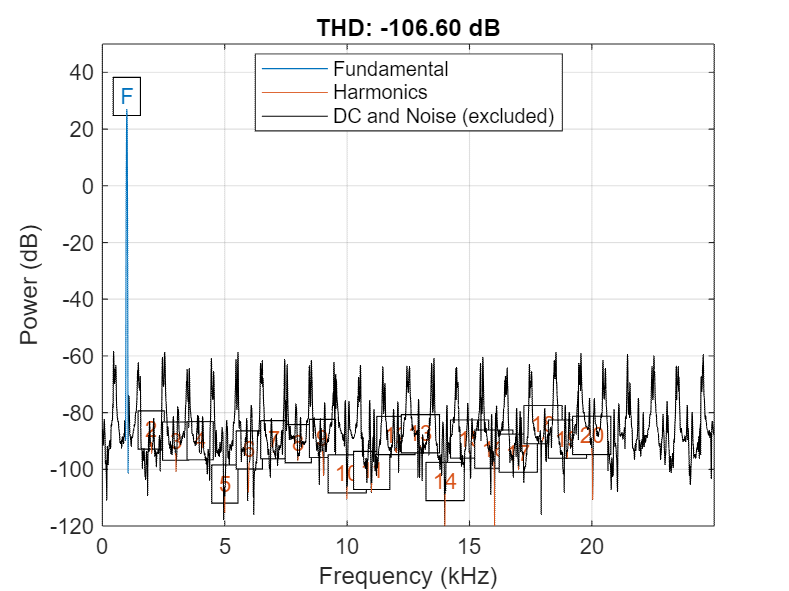

ans = -106.5976

thd(sampled,Fs,20)